% clear;
data = load('resultadosCSV_1_225mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*1.225e6)

T_buscado =      4.081632653061224e-07


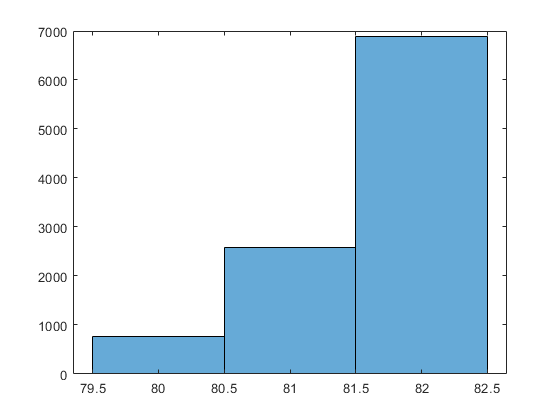

% t_fino = (start)*tau_start - (stop)*tau_stop;
t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse);


st = start-stop

st =   -104
  -102
   212
  -102
  -106
  -102
   210
  -104
  -102
   209


st_positivo = st(st>0);
std(st_positivo)

ans =    1.726402775617191


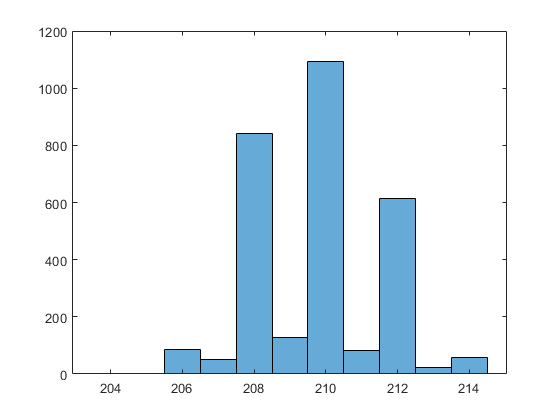

histogram(st(st>0))

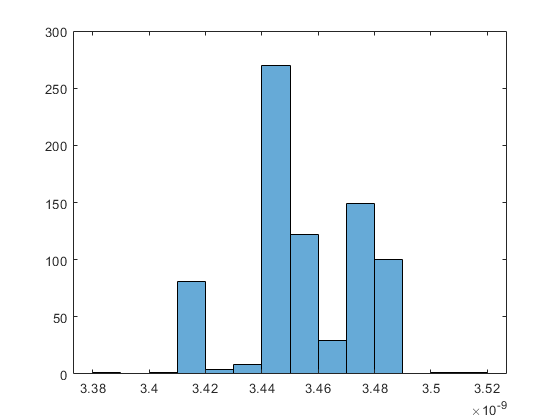


indices_80 = find(coarse==80);
indices_81 = find(coarse==81);
indices_82 = find(coarse==82);

%%Fino en 80
%%hay que sumarle una cuenta!!!
fino_80 = t_fino(indices_80);
coarse_80 = coarse(indices_80);
histogram(fino_80);

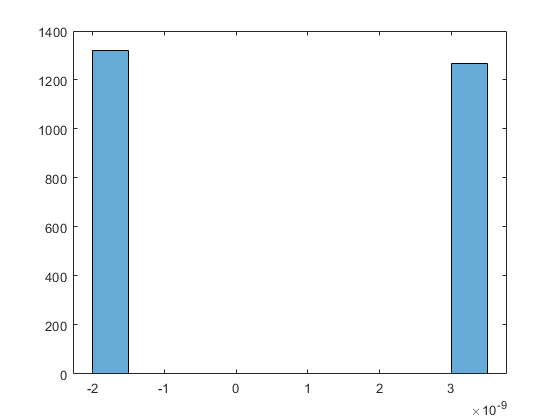


%%Fino en 81
fino_81 = t_fino(indices_81);
coarse_81 = coarse(indices_81);
histogram(fino_81);

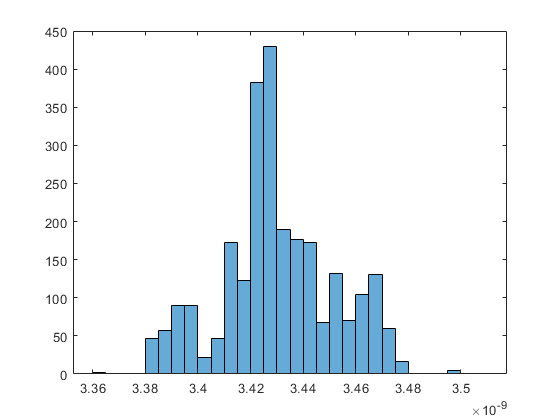

fino_81_buenos = fino_81(fino_81>0);
coarse_81_buenos = coarse_81(fino_81>0);
fino_81_malos  = fino_81(fino_81<0);
coarse_81_malos = coarse_81(fino_81<0);
histogram([fino_81_buenos; fino_81_malos+T])

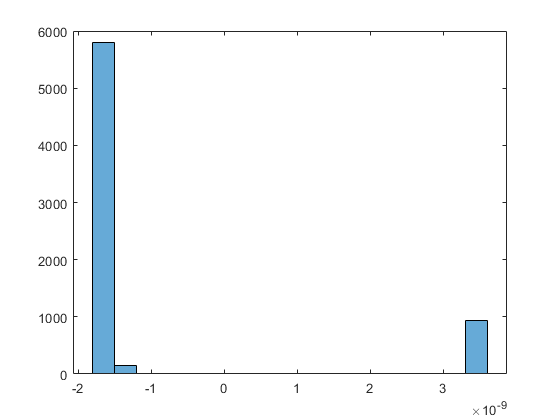


%Fino en 82
fino_82 = t_fino(indices_82);
coarse_82 = coarse(indices_82);
histogram(fino_82)

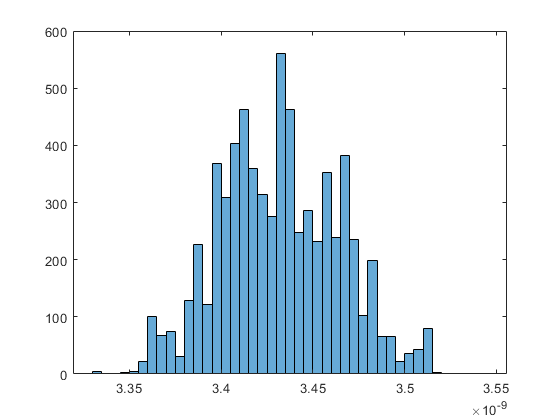

fino_82_buenos = fino_82(fino_82<0);
coarse_82_buenos = coarse_82(fino_82<0);
fino_82_malos  = fino_82(fino_82>0);
coarse_82_malos = coarse_82(fino_82>0);
histogram([fino_82_buenos+T; fino_82_malos])

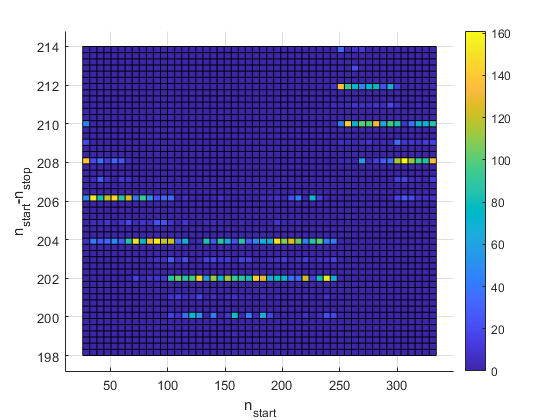

st = start-stop;
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
% std(st_positivo)
hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_1225M.eps');

clf;
y = [fino_80; fino_81_buenos; fino_81_malos+T; fino_82_buenos+T; fino_82_malos];
presicion = std(y)

presicion =      2.981934459866811e-11


media     = mean(y)

media =      3.433217416992188e-09


coarse_correcto = 81;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_80, fino_81_buenos, fino_81_malos+T, fino_82_buenos+T, fino_82_malos};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

sprintf("cantidad de coarse 80: %d", length(fino_80))

ans = "cantidad de coarse 80: 767"

sprintf("cantidad de coarse 81: %d", length(fino_81))

ans = "cantidad de coarse 81: 2588"

sprintf("cantidad de coarse 82: %d", length(fino_82))

ans = "cantidad de coarse 82: 6885"

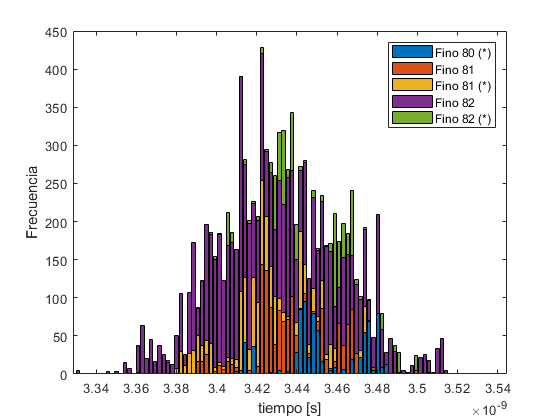

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Fino 80 (*)', 'Fino 81', 'Fino 81 (*)', 'Fino 82', 'Fino 82 (*)'});
exportgraphics(gcf,'histograma_1_225M.eps');


format long
T_buscado

T_buscado =      4.081632653061224e-07


Tiempo_final = 81*T + media

Tiempo_final =      4.084332174169922e-07


error = Tiempo_final - T_buscado

error =      2.699521108697568e-10


clf;

% Data vectors
data = {coarse_80, coarse_81_buenos, coarse_81_malos, coarse_82_buenos, coarse_82_malos};

% Number of bins
N = 16;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 79.5:0.25:83.5

commonEdges =   79.500000000000000  79.750000000000000  80.000000000000000  80.250000000000000  80.500000000000000  80.750000000000000  81.000000000000000  81.250000000000000  81.500000000000000  81.750000000000000  82.000000000000000  82.250000000000000  82.500000000000000  82.750000000000000  83.000000000000000  83.250000000000000  83.500000000000000


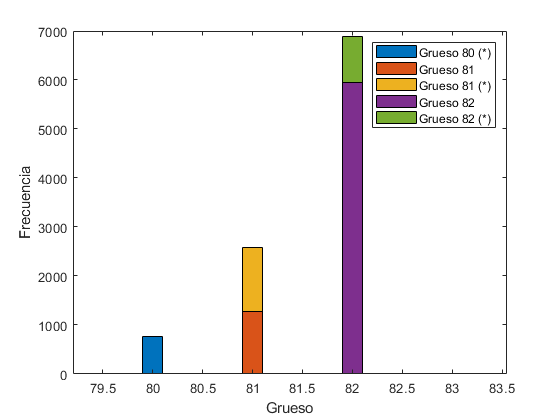


% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({'Grueso 80 (*)', 'Grueso 81', 'Grueso 81 (*)', 'Grueso 82', 'Grueso 82 (*)'});
exportgraphics(gcf,'histograma_coarse_1225M.eps');